# Find Nearest Neighbors

Find the patients in the `hospital` data set that most closely resemble the patients in `Y`, according to age and weight.

Load the `hospital` data set.

load hospital;
X = [hospital.Age hospital.Weight];

Visualise the data points on a scatter plot

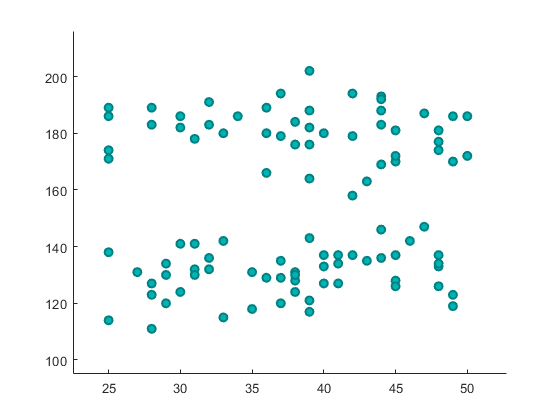

figure
scatter(X(:,1),X(:,2), ...
    'MarkerEdgeColor',[0 .5 .5], ...
    'MarkerFaceColor',[0 .7 .7], ...
    'LineWidth',1.5)

Y = [20 162; 30 169; 40 168; 50 170; 60 171];   % New patients

Perform a `knnsearch` between `X` and `Y` to find indices of nearest neighbors.

Idx = knnsearch(X,Y);
Idx

Idx =     96
    96
    41
    51
    20


Find the patients in `X` closest in age and weight to those in `Y`.

X(Idx,:)

ans =     25   171
    25   171
    39   164
    49   170
    50   172


*Copyright 2012 The MathWorks, Inc.*